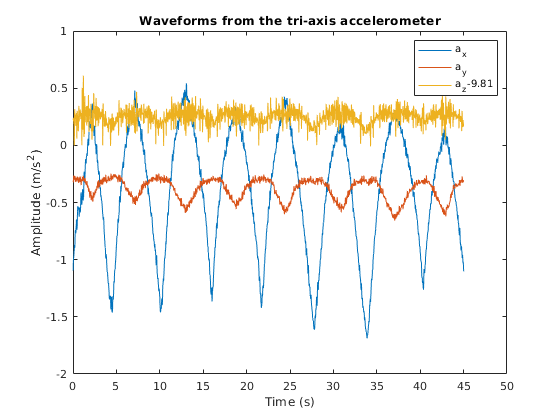

%Plotting the accelerometer signal

% Loading breathing data obtained after exercize
load('accel_gyro.mat')
figure
fs=50;
t=1/fs:1/fs:length(resp.gFXms2)/fs;
plot(t,resp.gFXms2,t,resp.gFYms2,t,resp.gFZms2-9.81)

xlabel('Time (s)')
ylabel('Amplitude (m/s^2)')
title('Waveforms from the tri-axis accelerometer')
legend(['a_x'],['a_y'],['a_z-9.81'])
%plot(t/60,mp36_s(1,:))
exportgraphics(gcf,"Fig10.9.jpg", 'Resolution',600)